# 1.1

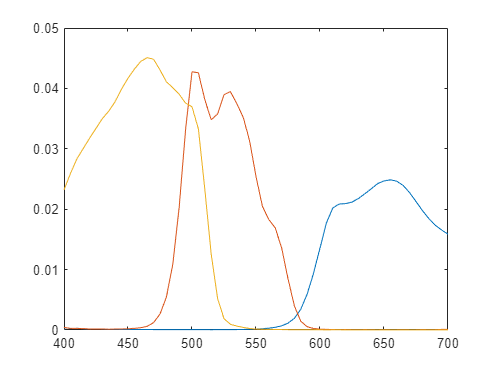

n = length(Ad);
x = linspace(400,700,n);
plot(x,Ad)

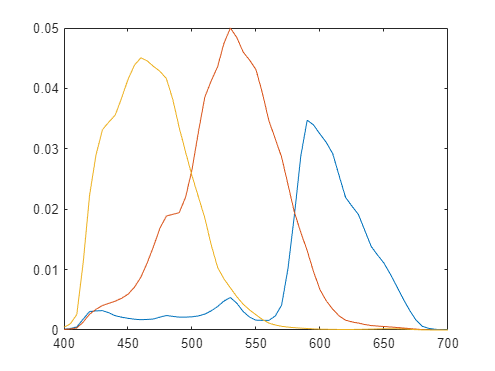

plot(x,Ad2)

Ad & Ad2 looks similar but not exact. They will definitly give different outputs. We think Ad2 will give a higher contrast image.

Answer: No.

# 1.2

## Camera 1

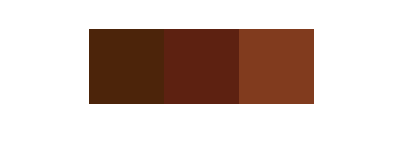

e = CIED65 .* chips20;

% raw (i.e. un-calibrated) camera output for the 20 surfaces
d = Ad'*e';

showRGB(d)

## Camera 2

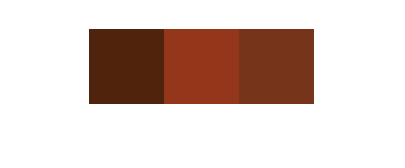

% raw (i.e. un-calibrated) camera output for the 20 surfaces
d = Ad2'*e';

showRGB(d)

# 2.1

e2 = ones(1,61)

% Ad_norm = normalize(Ad)
% Ad2_norm = normalize(Ad2)

d1 = Ad'*e2';
d2 = Ad2'*e2';

# 2.2

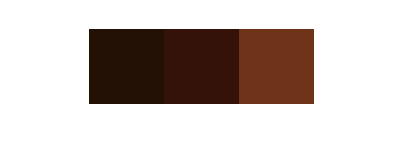

RGB_cal_D65 = raw .* d1;
RGB_cal_D65_2 = raw .* d2;

fprintf 
showRGB(RGB_cal_D65)

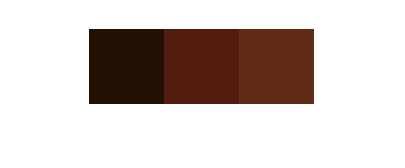

showRGB(RGB_cal_D65_2)

# 2.3

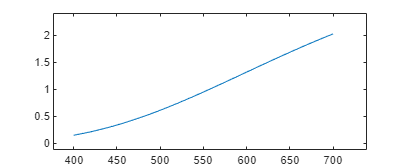

n = length(CIEA);
x = linspace(400,700,n);
plot(x,CIEA)
ylim([0,2.1])

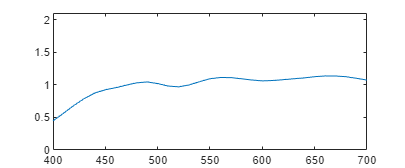

plot(x,CIEB)
ylim([0,2.1])

# 2.4

e = CIEA .* chips20;
e2 = CIEB .* chips20;

% raw data
d1_raw_indoor = Ad'*e';
d1_raw_outdoor = Ad'*e2';

% uncalibrated
e_norm = ones(1,61);

% calibration factors
d1_cf = Ad'*e_norm';

RGB_cal_CIEA = d1_raw_indoor .* d1_cf;
RGB_cal_CIEB = d1_raw_outdoor .* d1_cf;

showRGB(RGB_cal_D65)

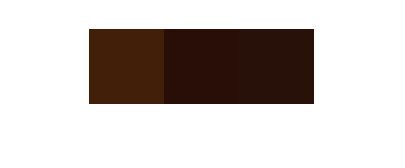

showRGB(RGB_cal_CIEA)

% showRGB(RGB_cal_CIEB)

# 2.5

R = ones(1,61);
d1 = Ad'*R;
d2 = Ad'*R;